## LQR Control

Q_var = {
    diag([100,  1,  100,  1]),   % 1: Baseline/Balanced
    diag([5000, 1,  100,  1]),   % 2: x Penalty
    diag([100,  1,  5000, 1]),   % 3: theta Penalty
    diag([100,  1, 5000,  5000]),  % 4: Higher theta Penalty
    diag([100, 1,  20000, 20000])    % 5: Aggressive theta Penalty
};

R = {
    5
    5
    5
    10
    20
};

R = 5×1 cell array
    {[ 5]}
    {[ 5]}
    {[ 5]}
    {[10]}
    {[20]}


## Simulation Setup

t = 0:0.01:10; 
C_cl = eye(4); 
D_cl = zeros(4, 1);

## Plotting Setup

% Labels and colors for plotting
labels = {
    'Q = diag[100,1,100,1]; R=5', 
    'Q = diag[5000,1,100,1]; R=5', 
    'Q = diag[100,1,5000,1]; R=5', 
    'Q = diag[100,1,5000,5000]; R=10', 
    'Q = diag[100,1,20000,20000]; R=20'};
colors = {'#0000FF', '#008000', '#FF0000', '#00C0C0', '#C000C0'};

%% Prepare Figure
figure('Name', 'LQR Weight Variations', 'Color', 'w', 'Position', [100 100 1000 800]);


## Simulation & Plotting Loop

for i = 1:length(Q_var)
% Get current Q matrix and calculate LQR gain K
    Q = Q_var{i};
    K = lqr(A, B, Q, R{i});

    C_track = [1 0 0 0];
    Nbar = -1 / (C_track * inv(A - B*K) * B);

    A_cl = A - B * K;
    B_cl = B * Nbar;

    sys_cl = ss(A_cl, B_cl, C_cl, D_cl);
    
    [Y, T, y] = step(sys_cl, t);

    disp('Nbar value:');
    disp(Nbar);

    disp('K value:');
    disp(K);

    assignin('base', 'K', K);
    assignin('base', 'Nbar', Nbar);

    % 1. Plot Cart Position (x)
    subplot(2,2,1);
    plot(t, y(:,1), 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    title('Cart Position ($x$)', 'Interpreter', 'latex'); xlabel('Time (s)'); ylabel('Position (m)'); grid on;

    % 2. Plot Cart Velocity (x_dot)
    subplot(2,2,2);
    plot(t, y(:,2), 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    title('Cart Velocity ($\dot{x}$)', 'Interpreter', 'latex'); xlabel('Time (s)'); ylabel('Velocity (m/s)'); grid on;

    % 3. Plot Pendulum Angle (theta)
    subplot(2,2,3);
    plot(t, y(:,3), 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    title('Pendulum Angle ($\theta$)', 'Interpreter', 'latex'); xlabel('Time (s)'); ylabel('Angle (rad)'); grid on;

    % 4. Plot Pendulum Angular Velocity (theta_dot)
    subplot(2,2,4);
    plot(t, y(:,4), 'Color', colors{i}, 'LineWidth', 1.5); hold on;
    title('Pendulum Angular Velocity ($\dot{\theta}$)', 'Interpreter', 'latex'); xlabel('Time (s)'); ylabel('Ang. Velocity (rad/s)'); grid on;
    
    % 5. Calculate time-domain metrics per output
    for k = 1:4
        s = stepinfo(y(:,k), t, 1); 
        SettlingTime(i,k) = s.SettlingTime;
        RiseTime(i,k)      = s.RiseTime;
        Overshoot(i,k)     = s.Overshoot;
        % steady-state error: final value against unit reference
        finalVal = y(end,k);
        SteadyStateError(i,k) = abs(1 - finalVal);
    end

    % 6. Control input --- u(t) = -K * x(t) + Nbar*1 
    U = (- (K * Y') )' + Nbar;

    % 7. Energy and average power
    Energy(i) = trapz(t, U.^2);       
    AvgPower(i) = Energy(i) / t(end);

    % 8. Approximate LQR cost integral --- J = ∫ (x'Qx + u'R u) dt
    integrand = zeros(length(t),1);
    for k = 1:length(t)
        xk = Y(k,:)';
        integrand(k) = xk' * Q * xk + U(k)^2 * Ri;
    end
    CostIntegral(i) = trapz(t, integrand);

end

Nbar value:


   -4.4721



K value:


   -4.4721  -22.3659  -77.6723  -12.9494



Nbar value:


  -31.6228



K value:


  -31.6228  -35.7083 -106.8279  -18.4086



Nbar value:


   -4.4721



K value:


   -4.4721  -22.7086  -87.0971  -13.5120



Nbar value:


   -3.1623



K value:


   -3.1623  -22.5252 -107.9269  -28.8033



Nbar value:


   -2.2361



K value:


   -2.2361  -22.0777 -120.3660  -37.4729



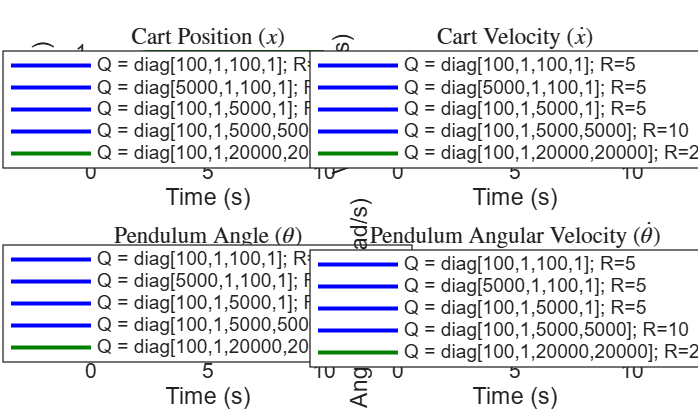


% Add legends to all subplots
for j = 1:4
    subplot(2,2,j);
    legend(labels, 'Location', 'best');
end

## Table

nVar = length(Q_var);
K_vals = zeros(nVar, 4);
Nbar_vals = zeros(nVar, 1);
caseLabel = strings(nVar,1);
SettlingTime = nan(nVar,4);
RiseTime = nan(nVar,4);
Overshoot = nan(nVar,4);
SteadyStateError = nan(nVar,4);
Energy = nan(nVar,1);
AvgPower = nan(nVar,1);
CostIntegral = nan(nVar,1);
CompTime = nan(nVar,1);

for i = 1:nVar
    Q = Q_var{i};
    Ri = R{i};
    K = lqr(A, B, Q, R{i});
    C_track = [1 0 0 0];
    Nbar = -1 / (C_track * inv(A - B*K) * B);

    % store
    K_vals(i, :) = K;        % row: [K1 K2 K3 K4]
    Nbar_vals(i) = Nbar;
    caseLabel(i) = labels{i};

end

% K & Nbar table
T = table(caseLabel, K_vals(:,1), K_vals(:,2), K_vals(:,3), K_vals(:,4), Nbar_vals, ...
    'VariableNames', {'Case', 'K1', 'K2', 'K3', 'K4', 'Nbar'});

disp(T);

                   Case                      K1         K2         K3         K4        Nbar  
    ___________________________________    _______    _______    _______    _______    _______

    "Q = diag[100,1,100,1]; R=5"           -4.4721    -22.366    -77.672    -12.949    -4.4721
    "Q = diag[5000,1,100,1]; R=5"          -31.623    -35.708    -106.83    -18.409    -31.623
    "Q = diag[100,1,5000,1]; R=5"          -4.4721    -22.709    -87.097    -13.512    -4.4721
    "Q = diag[100,1,5000,5000]; R=10"      -3.1623    -22.525    -107.93    -28.803    -3.1623
    "Q = diag[100,1,20000,20000]; R=20"    -2.2361    -22.078    -120.37    -37.473    -2.2361



% Performance Metrics Table
Case = labels(:);
Tmetrics = table(Case, CompTime, Energy, AvgPower, CostIntegral, ...
    'VariableNames', {'Case','CompTime_s','Energy_J','AvgPower_W','CostIntegral_J'});

disp(Tmetrics);

                    Case                     CompTime_s    Energy_J    AvgPower_W    CostIntegral_J
    _____________________________________    __________    ________    __________    ______________

    {'Q = diag[100,1,100,1]; R=5'       }       NaN          22.38        2.238          1065.6    
    {'Q = diag[5000,1,100,1]; R=5'      }       NaN         169.16       16.916           48474    
    {'Q = diag[100,1,5000,1]; R=5'      }       NaN         21.154       2.1154          1039.5    
    {'Q = diag[100,1,5000,5000]; R=10'  }       NaN         14.297       1.4297          780.28    
    {'Q = diag[100,1,20000,20000]; R=20'}       NaN         10.006       1.0006          569.81    




for k = 1:4
    colNames = {'Case', ['SettlingTime_o' num2str(k)], ['RiseTime_o' num2str(k)], ...
        ['Overshoot_o' num2str(k)], ['SSE_o' num2str(k)]};
    Tbl = table(Case, SettlingTime(:,k), RiseTime(:,k), Overshoot(:,k), SteadyStateError(:,k), ...
        'VariableNames', colNames);
    disp(['Output #' num2str(k) ' metrics:']);
    disp(Tbl);
end

Output #1 metrics:


                    Case                     SettlingTime_o1    RiseTime_o1    Overshoot_o1     SSE_o1  
    _____________________________________    _______________    ___________    ____________    _________

    {'Q = diag[100,1,100,1]; R=5'       }        9.2664            4.9501               0        0.01439
    {'Q = diag[5000,1,100,1]; R=5'      }        1.7302           0.86061        0.017913      5.973e-14
    {'Q = diag[100,1,5000,1]; R=5'      }        9.3026             4.991               0       0.014576
    {'Q = diag[100,1,5000,5000]; R=10'  }           NaN            6.9845               0       0.054271
    {'Q = diag[100,1,20000,20000]; R=20'}           NaN               NaN               0        0.13151



Output #2 metrics:


                    Case                     SettlingTime_o2    RiseTime_o2    Overshoot_o2    SSE_o2 
    _____________________________________    _______________    ___________    ____________    _______

    {'Q = diag[100,1,100,1]; R=5'       }          NaN                NaN              0       0.99354
    {'Q = diag[5000,1,100,1]; R=5'      }          NaN            0.10976         41.072             1
    {'Q = diag[100,1,5000,1]; R=5'      }          NaN                NaN              0       0.99339
    {'Q = diag[100,1,5000,5000]; R=10'  }          NaN                NaN              0       0.98277
    {'Q = diag[100,1,20000,20000]; R=20'}          NaN                NaN              0        0.9705



Output #3 metrics:


                    Case                     SettlingTime_o3    RiseTime_o3    Overshoot_o3    SSE_o3
    _____________________________________    _______________    ___________    ____________    ______

    {'Q = diag[100,1,100,1]; R=5'       }          NaN              NaN             0          1.0003
    {'Q = diag[5000,1,100,1]; R=5'      }          NaN              NaN             0               1
    {'Q = diag[100,1,5000,1]; R=5'      }          NaN              NaN             0          1.0003
    {'Q = diag[100,1,5000,5000]; R=10'  }          NaN              NaN             0          1.0006
    {'Q = diag[100,1,20000,20000]; R=20'}          NaN              NaN             0          1.0007



Output #4 metrics:


                    Case                     SettlingTime_o4    RiseTime_o4    Overshoot_o4    SSE_o4 
    _____________________________________    _______________    ___________    ____________    _______

    {'Q = diag[100,1,100,1]; R=5'       }          NaN                NaN              0       0.99987
    {'Q = diag[5000,1,100,1]; R=5'      }          NaN           0.013032         123.58             1
    {'Q = diag[100,1,5000,1]; R=5'      }          NaN                NaN              0       0.99986
    {'Q = diag[100,1,5000,5000]; R=10'  }          NaN                NaN              0       0.99982
    {'Q = diag[100,1,20000,20000]; R=20'}          NaN                NaN              0       0.99985

